## Load input

[input, Fs] = audioread("ichika.mp3");
Fnyq = Fs / 2;
input = sum(input, 2) / 2; % Stero to mono
input_duration = 9;
% Fragmento de input_duration segundos
input = input(1:floor(input_duration*Fs));
%input = rand(48000*8,1)

## Input FFT

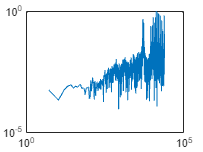

y = fft(input);
input_duration_millis = input_duration*1000;
P2 = abs(y/input_duration_millis);
P1 = P2(1:input_duration_millis/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(input_duration_millis/2))/input_duration_millis;
loglog(f,abs(P1));

## Low pass test

wp = 2000;
[b,a] = cheby2(4, 60, wp/Fnyq);
sos = tf2sos(b,a);
y_lptest = sosfilt(sos, input);
audiowrite('output.wav', y_lptest, Fs);

## Create peak filter

Q = 10;
np_filter = dsp.NotchPeakFilter('Specification',...
    'Quality factor and center frequency',...
    'QualityFactor',Q,...
    'SampleRate',Fs,'CenterFrequency',800);

% [~,~,Bpeak,Apeak]=tf(np_filter);

## Create peak frequency vector

% Simulation time management
samples_per_frame = 100;
total_samples = length(input);
total_frames = floor(total_samples / samples_per_frame);

% Notch filter parameters - how they vary over time
wah_freq = 3;
wah_pulse = 2*pi*wah_freq;

t_inc = samples_per_frame / Fs;
t_points = (0:total_frames-1)*t_inc;

wah_amount = 10.^cos(wah_pulse*t_points);
wah_amount = map(wah_amount, [0.1, 10], [0 ,1]);

% wah_amount = cos(wah_pulse*t_points);
% wah_amount = map(wah_amount, [-1, 1], [0 ,1]);

peak_freqs = map(wah_amount, [0, 1], [200, 1000]);   % Peak frequencies
peak_qs = map(wah_amount, [0, 1], [15, 10]);

% % Scope creation
scope = spectrumAnalyzer('SampleRate', Fs, ...
    'AveragingMethod','exponential',...
    'ForgettingFactor',.75,...
    'ChannelNames',{'Filter 1'},...
    'ShowLegend',true);

## Generate output

y = [];
zf = [];
% Actual simulation loop
for loop_i = 0:(total_frames-1)
    % Update filter parameters
    peak_freq = peak_freqs(loop_i+1);
    peak_q = peak_qs(loop_i+1);
    np_filter.CenterFrequency = peak_freq;
    %np_filter.QualityFactor = peak_q;

    upper_limit = min([loop_i*samples_per_frame + samples_per_frame, total_samples]);
    % Filter noise
    sample = input(loop_i*samples_per_frame + 1:upper_limit);

    [~, y_peak] = np_filter(sample);
   
    [b,a] = cheby2(2, 60, (peak_freq+200)/Fnyq);
    [y_lp, zf] = filter(b,a, sample, zf);
    y_frame = y_peak*0.4;
    y = [y; y_frame];
    %scope(y_lp,y_peak,y_frame);
   %scope(y_frame);
   %pause(samples_per_frame/Fs);
end
sound(y, Fs, 16);
audiowrite('output.wav', y, Fs);

## FFT Comparison

signals = [y,y_lptest];
signals_fft = fft(signals, [], 1);
%signals_fft = signals_fft(:, 1) - signals_fft(:, 2);
L=length(y);
P2 = abs(signals_fft/L);
P1 = P2(1:L/2+1,1:end);
P1(2:end-1,1:end) = 2*P1(2:end-1,1:end);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")
legend

function [y] = map(x, r1, r2)
relative_offset = (x - r1(1)) / (r1(2) - r1(1));
y = relative_offset * (r2(2) - r2(1)) + r2(1);
end